# HW 7

% Monte Carlo
rng("default"); % For reproducibility

% Define total number of iterations
N = 10^7; % Don't try to generate more than 10^7 random coordinates (from 10^8 the plot breaks,
          % from 10^9 the calculations take almost 20 GiB of RAM)  :)
pi_estimate = zeros(1, N); % Array for storing the estimated numbers of pi

% Perform the Monte Carlo simulation
x = rand(N, 1); % Generate random x-coordinates of a point
y = rand(N, 1); % Generate random y-coordinates of a point
in_circle = 0; % Later used to find the position of the point

for i = 1:N
    if (x(i)^2 + y(i)^2) <= 1
        in_circle = in_circle + 1; % Used to determine if the point is in the circle
    end
    pi_estimate(i) = 4 * in_circle / i; % Estimate π at current iteration
end

iteration_counts = [10^2, 10^4, 10^6];
relative_error = zeros(size(iteration_counts));
for i = 1:length(iteration_counts)
    relative_error(i) = abs((pi_estimate(iteration_counts(i)) - pi) / pi) * 100;
end

disp('Relative Error (%) for Specific Iteration Counts:');

Relative Error (%) for Specific Iteration Counts:


disp(table(iteration_counts', relative_error', ...
    'VariableNames', {'Iterations', 'RelativeError'}));

    Iterations    RelativeError
    __________    _____________

        100           5.7803   
      10000          0.31854   
      1e+06         0.034144   



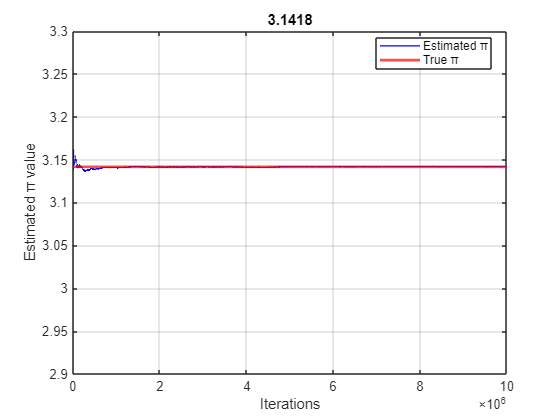


% Plot
figure;
plot(1:N, pi_estimate, 'b-', 'LineWidth', 1);
hold on;
yline(pi, 'color', 'r', 'LineWidth', 2); % Red line at π (copy from HW7.pdf)
xlabel('Iterations');
ylabel('Estimated π value');
title([num2str(pi_estimate(end))]);
axis([0 N 2.9 3.3]);
grid on;
legend('Estimated π', 'True π', 'Location', 'best');
hold off;